clear; clc

addpath('geodesy');

interp_list = [1,5];
% ref_sensors = {'Alcorcon1','chamberi','madrid_city_1','rack_1'};
ref_sensors = {'chamberi'};
results = containers.Map;

for ref_index = 1:length(ref_sensors)
    ref_sensor = ref_sensors{ref_index};
    N = length(interp_list);
    data = struct('interp',cell(N,1),'nlls',cell(N,1),'nlop',cell(N,1),'lls',cell(N,1));
    for interp = 1:N
        load(sprintf('results_real/20210602_i%d_%s.mat',interp_list(interp),ref_sensor));
        
        data(interp).interp = [interp_list(interp)];
    
        unknown_coordinates = problem_data.transmitters.unknown.coord;
        nlls_coordinates = nlls(:,1:2);
        nlop_coordinates = nlop(:,1:2);
%         nlop_l1_coordinates = nlop_l1(:,1:2);
%         nlop_l1l2_coordinates = nlop_l1l2(:,1:2);
        
        nlls_error = zeros(size(nlls,1),1);
        nlop_error = zeros(size(nlop,1),1);
%         nlop_l1_error = zeros(size(nlop,1),1);
%         nlop_l1l2_error = zeros(size(nlop,1),1);
        lls_error = zeros(size(lls,1),1);
        
        for ii = 1:length(nlls_error)
            nlls_error(ii) = vdist(nlls_coordinates(ii,1),nlls_coordinates(ii,2),unknown_coordinates(1),unknown_coordinates(2));
            nlop_error(ii) = vdist(nlop_coordinates(ii,1),nlop_coordinates(ii,2),unknown_coordinates(1),unknown_coordinates(2));
%             nlop_l1_error(ii) = vdist(nlop_l1_coordinates(ii,1),nlop_l1_coordinates(ii,2),unknown_coordinates(1),unknown_coordinates(2));
%             nlop_l1l2_error(ii) = vdist(nlop_l1l2_coordinates(ii,1),nlop_l1l2_coordinates(ii,2),unknown_coordinates(1),unknown_coordinates(2));
            lls_error(ii) = vdist(lls(ii,1),lls(ii,2),unknown_coordinates(1),unknown_coordinates(2));
        end
        
        data(interp).nlls = nlls_error;
        data(interp).nlop = nlop_error;
%         data(interp).nlop_l1 = nlop_l1_error;
%         data(interp).nlop_l1l2 = nlop_l1l2_error;
        data(interp).lls = lls_error;
    end
    
    results(ref_sensor) = data;
end

## Looking at only one sensor

target_sensor = 'chamberi';
data = results(target_sensor);

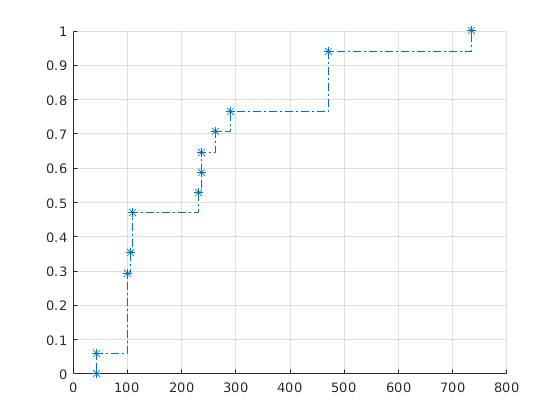

figure();
hold on;
grid on;

% NLLS ecdf
% [f_nlls, x_nlls] = ecdf(data(1).nlls);
% stairs(x_nlls,f_nlls,'LineStyle',"-.",'Marker','d');

% NLOP ecdf
[f_nlop, x_nlop] = ecdf(data(1).nlop);
stairs(x_nlop,f_nlop,'LineStyle',"-.",'Marker','*');


% L1 ecdf
[f_nlop_l1, x_nlop_l1] = ecdf(data(1).nlop_l1);

Reference to non-existent field 'nlop_l1'.

stairs(x_nlop_l1,f_nlop_l1,'LineStyle',"-.",'Marker','*');

% L1-L2 ecdf
[f_nlop_l1l2, x_nlop_l1l2] = ecdf(data(1).nlop_l1l2);
stairs(x_nlop_l1l2,f_nlop_l1l2,'LineStyle',"-.",'Marker','*');

% LLS ecdf
% [f_lls, x_lls] = ecdf(data(1).lls);
% stairs(x_lls,f_lls,'LineStyle',"-.","Marker","o")

% legend('trust-region','BFGS','LLS','Location','southeast');
legend('BFGS','BFGS-L1', 'BFGS-L1-L2', 'LLS','Location','southeast');

title(sprintf('Interpolation (%d)',data(1).interp));
xlabel('Error (m)');
ylabel('Fraction');
hold off;

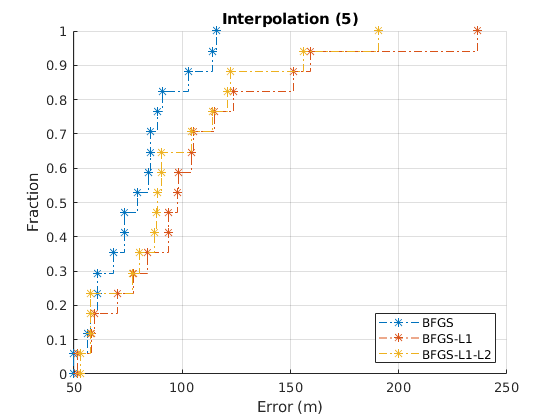

figure();
hold on;
grid on;

% NLLS ecdf
% [f_nlls, x_nlls] = ecdf(data(2).nlls);
% stairs(x_nlls,f_nlls,'LineStyle',"-.",'Marker','d');

% NLOP ecdf
[f_nlop, x_nlop] = ecdf(data(2).nlop);
stairs(x_nlop,f_nlop,'LineStyle',"-.",'Marker','*');

% L1 ecdf
[f_nlop_l1, x_nlop_l1] = ecdf(data(2).nlop_l1);
stairs(x_nlop_l1,f_nlop_l1,'LineStyle',"-.",'Marker','*');

% L1-L2 ecdf
[f_nlop_l1l2, x_nlop_l1l2] = ecdf(data(2).nlop_l1l2);
stairs(x_nlop_l1l2,f_nlop_l1l2,'LineStyle',"-.",'Marker','*');

% LLS ecdf
% [f_lls, x_lls] = ecdf(data(2).lls);
% stairs(x_lls,f_lls,'LineStyle',"-.","Marker","o")

legend('BFGS','BFGS-L1', 'BFGS-L1-L2','LLS','Location','southeast');

title(sprintf('Interpolation (%d)',data(2).interp));
xlabel('Error (m)');
ylabel('Fraction');
hold off;

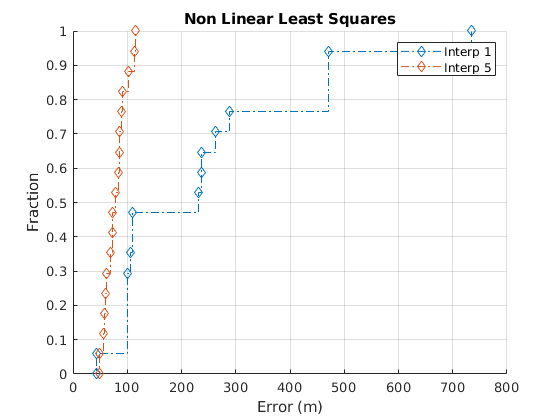

figure();
hold on;
grid on;

% NLLS ecdf
[f_nlls, x_nlls] = ecdf(data(1).nlls);
stairs(x_nlls,f_nlls,'LineStyle',"-.",'Marker','d');

% NLLS ecdf
[f_nlls, x_nlls] = ecdf(data(2).nlls);
stairs(x_nlls,f_nlls,'LineStyle',"-.",'Marker','d');

title('Non Linear Least Squares');
legend('Interp 1', 'Interp 5');
xlabel('Error (m)');
ylabel('Fraction');

hold off;

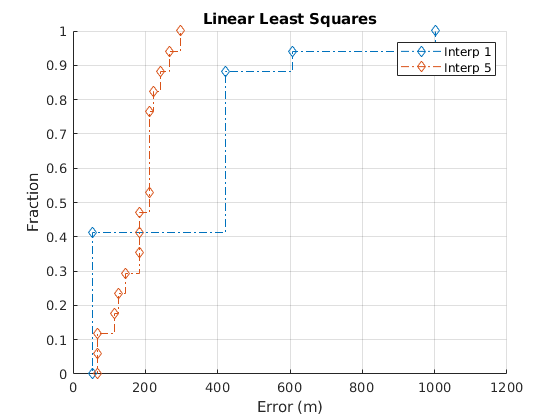

figure();
hold on;
grid on;

% NLLS ecdf
[f_lls, x_lls] = ecdf(data(1).lls);
stairs(x_lls,f_lls,'LineStyle',"-.",'Marker','d');

% NLLS ecdf
[f_lls, x_lls] = ecdf(data(2).lls);
stairs(x_lls,f_lls,'LineStyle',"-.",'Marker','d');

title('Linear Least Squares');
legend('Interp 1', 'Interp 5');
xlabel('Error (m)');
ylabel('Fraction');

hold off;

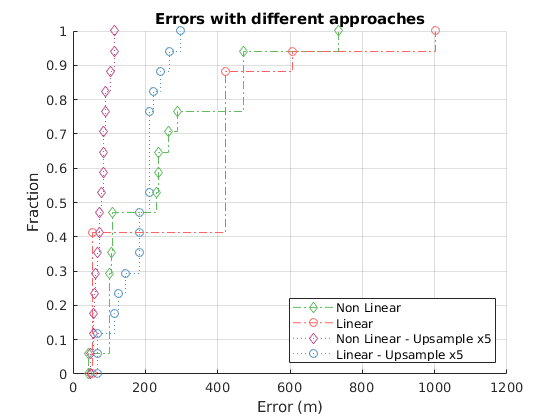

figure();
hold on;
grid on;

% NLLS ecdf
[f_nlls, x_nlls] = ecdf(data(1).nlls);
stairs(x_nlls,f_nlls,'Color','#63bb61','LineStyle',"-.",'Marker','d');

% LLS ecdf
[f_lls, x_lls] = ecdf(data(1).lls);
stairs(x_lls,f_lls,'Color','#ff6361','LineStyle',"-.","Marker","o")

% NLLS ecdf
[f_nlls, x_nlls] = ecdf(data(2).nlls);
stairs(x_nlls,f_nlls,'Color','#bc5090','LineStyle',":",'Marker','d');

% LLS ecdf
[f_lls, x_lls] = ecdf(data(2).lls);
stairs(x_lls,f_lls,'Color','#5090bc','LineStyle',":","Marker","o")

% title(target_sensor,'Interpreter', 'none');
title('Errors with different approaches')
legend('Non Linear', 'Linear', 'Non Linear - Upsample x5', 'Linear - Upsample x5', 'Location',"southeast");
xlabel('Error (m)');
ylabel('Fraction');

hold off;

## Looking at all sensors as reference

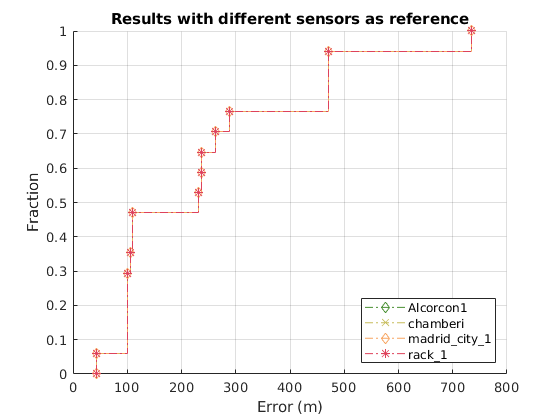

figure();
hold on;
grid on;

% 'Alcorcon1','chamberi','madrid_city_1','rack_1'
% 
data = results(ref_sensors{1});
[f_nlls, x_nlls] = ecdf(data(1).nlls);
stairs(x_nlls,f_nlls,'Color','#488f31','LineStyle',"-.",'Marker','d');

%
data = results(ref_sensors{2});
[f_lls, x_lls] = ecdf(data(1).nlls);
stairs(x_lls,f_lls,'Color','#c7bd5b','LineStyle',"-.","Marker","x")

% 
data = results(ref_sensors{3});
[f_nlls, x_nlls] = ecdf(data(1).nlls);
stairs(x_nlls,f_nlls,'Color','#f7a460','LineStyle',"-.",'Marker','d');

% 
data = results(ref_sensors{4});
[f_lls, x_lls] = ecdf(data(1).nlls);
stairs(x_lls,f_lls,'Color','#de425b','LineStyle',"-.","Marker","*")

title('Results with different sensors as reference');
legend(ref_sensors, 'Location',"southeast",'Interpreter',"none");
xlabel('Error (m)');
ylabel('Fraction');

hold off;

load('20210720_chamberi_no_interp.mat');
load('20210720_chamberi_no_interp_2.mat');
load('20210720_chamberi_no_corr_i5.mat');

for ii = 1:length(nlls_error)
    nlop_error_noin(ii) = vdist(nlop_noin(ii,1),nlop_noin(ii,2),unknown_coordinates(1),unknown_coordinates(2));
    nlop_error_noin_noavg(ii) = vdist(nlop_noin_noavg(ii,1),nlop_noin_noavg(ii,2),unknown_coordinates(1),unknown_coordinates(2));
    nlop_error_noin_int(ii) = vdist(nlop(ii,1),nlop(ii,2),unknown_coordinates(1),unknown_coordinates(2));
end

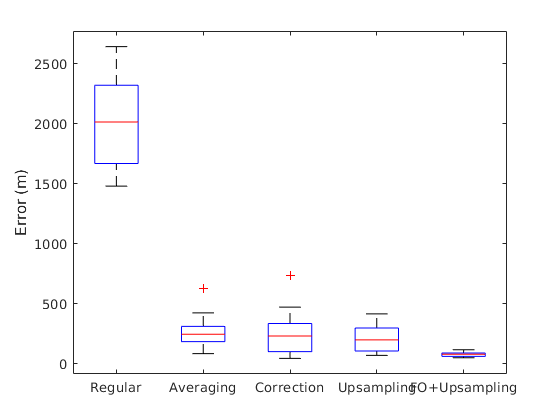

boxplot([nlop_error_noin_noavg',nlop_error_noin',data(1).nlop,nlop_error_noin_int', data(2).nlop],{'Regular','Averaging','Correction','Upsampling','FO+Upsampling'});
ylabel("Error (m)");